Input figures

imagepath_nf = 'VRConversions/NoFilter.bmp'

imagepath_nf = 'VRConversions/NoFilter.bmp'

imagepath_f = 'VRConversions/Filter.bmp'

imagepath_f = 'VRConversions/Filter.bmp'


image_nf = imread(imagepath_nf);
image_f = imread(imagepath_f);

# PX & MM

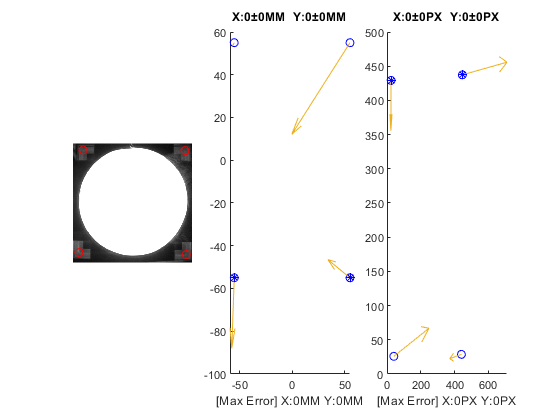

units = {'PX','MM'};

% Extract known points from image
clear checker
figure
imshow(image_f)
[checker(:,1),checker(:,2)] = getpts;
close

coord = [
    -55 -55;...
    55 -55;...
    55 55;...
    -55 55;...
    ];

% Get Transformation Matrix
PX2MM = homography_solve(checker', coord');
MM2PX = homography_solve(coord', checker');

% Save
dlmwrite(strcat('VRConversions/',units{1},'2',units{2},'.txt'),PX2MM);
dlmwrite(strcat('VRConversions/',units{2},'2',units{1},'.txt'),MM2PX);

plotHomographyResult(units,image_f,checker,coord,PX2MM,MM2PX)

# PXnf & PX

% units = {'PXnf','MM'};
% 
% % Extract known points from image
% clear checkernf
% figure
% imshow(image_nf)
% [checkernf(:,1),checkernf(:,2)] = getpts;
% close
% 
% % Get Transformation Matrix
% PXnf2PX = homography_solve(checkernf', checker');
% PX2PXnf = homography_solve(checker', checkernf');
% 
% % Save
% % dlmwrite(strcat('VRConversions/',units{1},'2',units{2},'.txt'),PXnf2MM);
% % dlmwrite(strcat('VRConversions/',units{2},'2',units{1},'.txt'),MM2PXnf);
% 
% plotHomographyResult(units,[],checkernf,checker,PXnf2PX,PX2PXnf)

# PXnf & VR

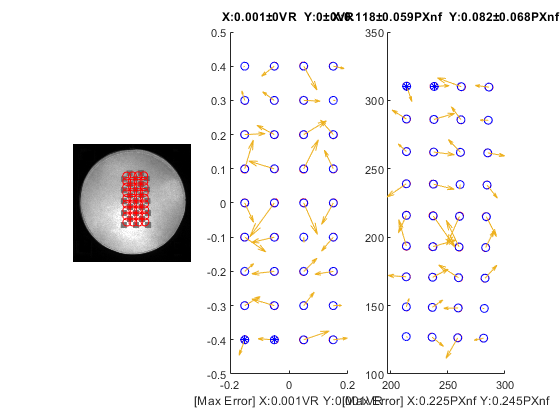

units = {'PXnf','VR'};

checker = detectCheckerboardPoints(image_nf);

coord =[
    -0.15 -0.4; -0.05 -0.4; 0.05 -0.4; 0.15 -0.4;
    -0.15 -0.3; -0.05 -0.3; 0.05 -0.3; 0.15 -0.3;
    -0.15 -0.2; -0.05 -0.2; 0.05 -0.2; 0.15 -0.2;
    -0.15 -0.1; -0.05 -0.1; 0.05 -0.1; 0.15 -0.1;
    -0.15 0; -0.05 0; 0.05 0; 0.15 0;
    -0.15 0.1; -0.05 0.1; 0.05 0.1; 0.15 0.1;
    -0.15 0.2; -0.05 0.2; 0.05 0.2; 0.15 0.2;
    -0.15 0.3; -0.05 0.3; 0.05 0.3; 0.15 0.3;
    -0.15 0.4; -0.05 0.4; 0.05 0.4; 0.15 0.4;
    ];

% Get Transformation Matrix
PXnf2VR = homography_solve(checker', coord');
VR2PXnf = homography_solve(coord', checker');

% Save
% dlmwrite(strcat('VRConversions/',units{1},'2',units{2},'.txt'),PXnf2VR);
% dlmwrite(strcat('VRConversions/',units{2},'2',units{1},'.txt'),VR2PXnf);

plotHomographyResult(units,image_nf,checker,coord,PXnf2VR,VR2PXnf)

# VR & MM

units = {'VR','MM'};

% % Get Transformation Matrix
% VR2MM = PX2MM*PXnf2PX*VR2PXnf;
% MM2VR = PXnf2VR*PX2PXnf*MM2PX;
% Get Transformation Matrix
VR2MM = PX2MM*VR2PXnf;
MM2VR = PXnf2VR*MM2PX;

% Save
dlmwrite(strcat('VRConversions/',units{1},'2',units{2},'.txt'),VR2MM);
dlmwrite(strcat('VRConversions/',units{2},'2',units{1},'.txt'),MM2VR);

# VL & MM

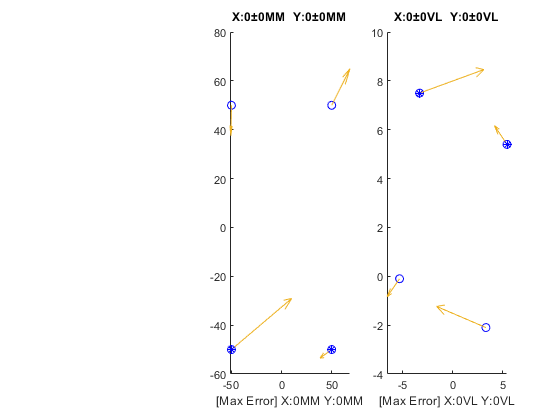

units = {'VL','MM'};

%Voltage Matrix in Volts (curve)
checker = [
    5.4 5.4;...
    -3.3 7.5;...
    -5.3 -0.1;...
    3.3 -2.1;...
    ];

%Real Matrix in Millimeters (curve)
coord = [
    -50 -50;...
    50 -50;...
    50 50;...
    -50 50;...
    ];

% Get Transformation Matrix
VL2MM = homography_solve(checker', coord');
MM2VL = homography_solve(coord', checker');

% Save
dlmwrite(strcat('VRConversions/',units{1},'2',units{2},'.txt'),VL2MM);
dlmwrite(strcat('VRConversions/',units{2},'2',units{1},'.txt'),MM2VL);

plotHomographyResult(units,[],checker,coord,VL2MM,MM2VL)